## Definitions of constants/variables

symbol_num = 10000;
symbols = importdata("const_rand_symbols.mat"); %randi([0 3],Symbol_Num,1)
rand_sym_noise=importdata("const_rand_sym_noise.mat");
symbol_rate = 100e9; %Hz
time_step = 1/symbol_rate; %seconds
linewidth = 100e3; %Hz
variance=2*pi*linewidth*time_step;

## QPSK using the communications toolbox

To Do

> create different amounts of noise

> SNR vs BER (as noise increases there will be a limiing error rate)

(Later mutual information)


modulated_symbols = pskmod(symbols,4,0,'gray');

demod_symbols = pskdemod(modulated_symbols,4,0,'gray');

%%%Phase noise modeled as random walk%%%
%The cummulative sum of the standard deviations of each symbol's 
% phase as they are passed through the channel

%phase_noise=cumsum(sqrt(variance)randn(symbol_num,1));

sets = logspace(1,9,10);
sets_num= size(sets,2);

variances = variance .* sets;

%phase_noise=cumsum(sqrt(variance)*const_rand_sym_noise);
phase_noise_sets = zeros(symbol_num,sets_num);

for i=1:size(variances,2)
    phase_noise_sets(:,i) = cumsum(sqrt(variances(:,i)).*const_rand_sym_noise);
end   

noisy_modulated_symbols = modulated_symbols .* phase_noise_sets;

noisy_demod_symbols = pskdemod(noisy_modulated_symbols,4,0,"gray");


## Plotting QPSK output, after noise has been added

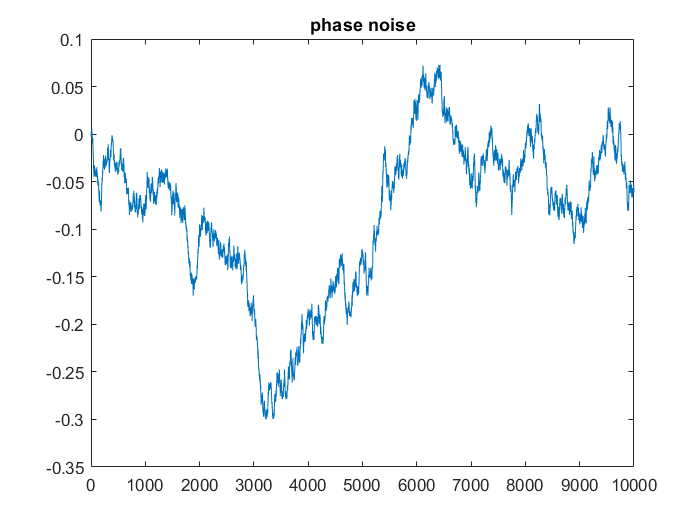

figure
plot(phase_noise)
title('phase noise')

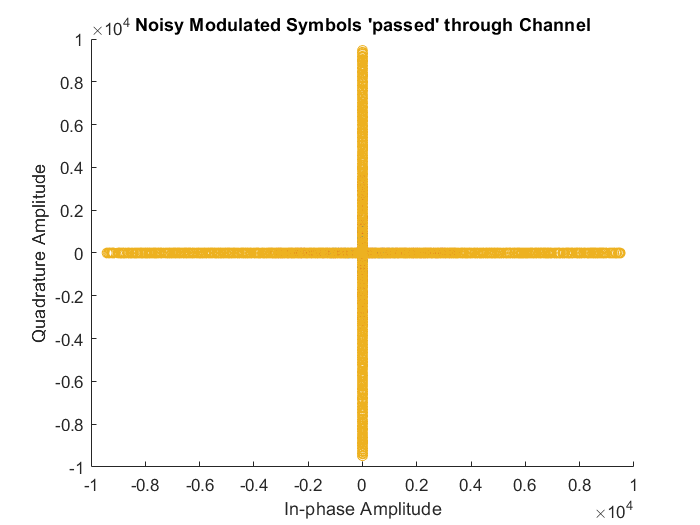


figure
hold on
for i=1:size(noisy_modulated_symbols,2)
    scatter(real(noisy_modulated_symbols(:,i)),imag(noisy_modulated_symbols(:,i)))
end
title("Noisy Modulated Symbols 'passed' through Channel")
xlabel("In-phase Amplitude")
ylabel("Quadrature Amplitude")
hold off

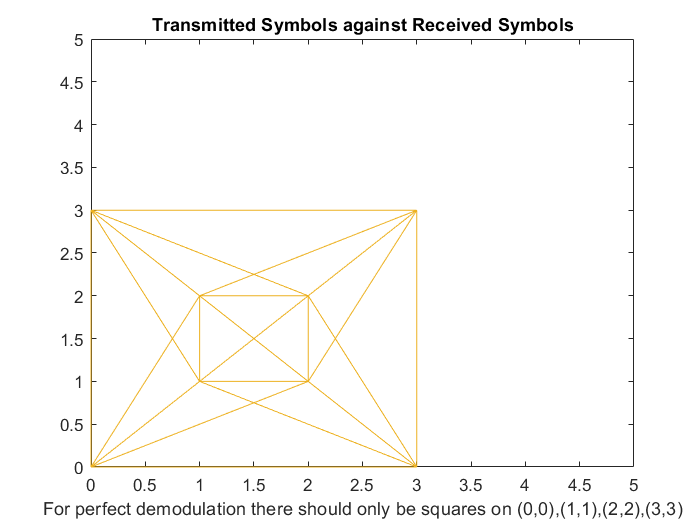

%{
figure
scatter(real(noisy_demod_symbols),imag(noisy_demod_symbols),"filled","d")
title("Demodulated Noisy Symbols 'passed' through Channel")
%}

figure
plot(noisy_demod_symbols,symbols)
title("Transmitted Symbols against Received Symbols")
xlabel("For perfect demodulation there should only be squares on (0,0),(1,1),(2,2),(3,3)")
%plot(modulated_symbols)
axis([0,5,0,5])

%grid on

## SNR and BER

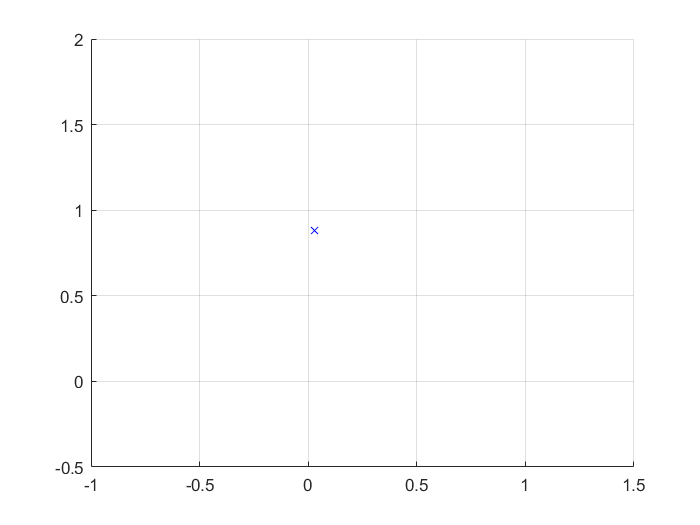

figure
hold on
for i=1:size(noisy_demod_symbols,2)
    [SNR,noisePow] = snr(symbols,noisy_demod_symbols(:,i)); %All in dB
    [num_of_errs,BER] = biterr(symbols,noisy_demod_symbols(:,i),2);
    plot(SNR,BER,"bx--")
    grid on
end